# Trajectories

## Cubic interpolation. Equations

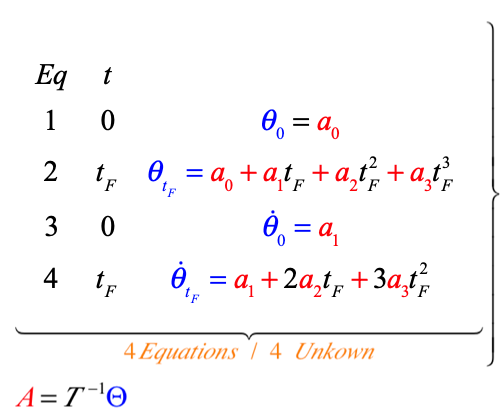

In matrix form

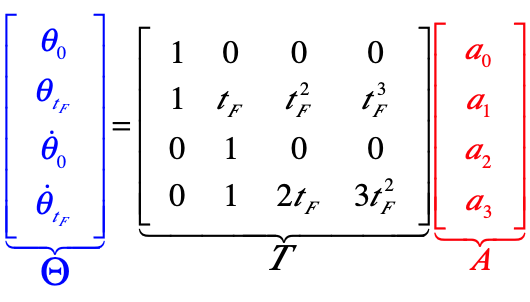

## Initial conditions. Coefficients

Let's try


$$  {\theta _0} = 0 \\
  {\theta _F} = 1 \\
 {{\dot \theta }_0} = 0 \\
 {{\dot \theta }_F} = 0 
\end{gathered} \]$$


clear
t=(0:0.1:2)'

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


Q=[0 1 0 0]' 

Q =      0
     1
     0
     0


T=[1 0 0 0;...
   1 2 4 8;...
   0 1 0 0;...
   0 1 4 12]

T =      1     0     0     0
     1     2     4     8
     0     1     0     0
     0     1     4    12


A=inv(T)*Q

A =          0
         0
    0.7500
   -0.2500


## Profiles 

Angle, angular velocity and angular aceleration profiles

### Angle $\left\lbrack \begin{array}{c}
\textrm{rad}
\end{array}\right\rbrack$


$$\[\theta (t) = {a_0} + {a_1}t + {a_2}{t^2} + {a_3}{t^3}\]$$


q=A(1)+A(2).*t+A(3).*t.^2+A(4).*t.^3

q =          0
    0.0073
    0.0280
    0.0608
    0.1040
    0.1562
    0.2160
    0.2818
    0.3520
    0.4253


### Angular speed $\left\lbrack \begin{array}{c}
\frac{\textrm{rad}}{s}
\end{array}\right\rbrack$


$$\[\dot \theta (t) = {a_1} + 2{a_2}t + 3{a_3}{t^2}\]$$


q_dot=A(2)+2*A(3).*t+3*A(4).*t.^2

q_dot =          0
    0.1425
    0.2700
    0.3825
    0.4800
    0.5625
    0.6300
    0.6825
    0.7200
    0.7425


### Angular aceleration $\left\lbrack \begin{array}{c}
\frac{\textrm{rad}}{s^2 }
\end{array}\right\rbrack$

q_2dot=2*A(3)+6*A(4).*t

q_2dot =     1.5000
    1.3500
    1.2000
    1.0500
    0.9000
    0.7500
    0.6000
    0.4500
    0.3000
    0.1500


### Ploting result

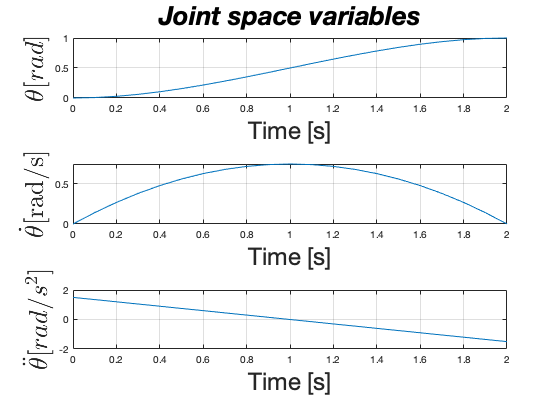

subplot(3,1,1)
plot(t,q)
title('Joint space variables','FontAngle','italic','FontSize',26);
ylabel('$\theta [rad]$','FontSize',26,'Interpreter','latex');
xlabel('Time [s]','FontSize',24);
grid on
subplot(3,1,2)
%ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
plot(t,q_dot)
xlabel('Time [s]','FontSize',24);
ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
grid on
subplot(3,1,3)
plot(t,q_2dot)
xlabel('Time [s]','FontSize',24);
ylabel('$\ddot \theta [rad/s^2]$','FontSize',26,'Interpreter','latex');
grid on

## Example

Let's try


$$  {\theta _0} = 2 \\
  {\theta _F} = 5 \\
 {{\dot \theta }_0} = 0.5 \\
 {{\dot \theta }_F} = 1 
\end{gathered} \]$$


t=(0:0.1:2)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000


Q=[2 5 0.5 1]'

Q =     2.0000
    5.0000
    0.5000
    1.0000


T=[1 0 0 0;...
   1 2 4 8;...
   0 1 0 0;...
   0 1 4 12]

T =      1     0     0     0
     1     2     4     8
     0     1     0     0
     0     1     4    12


A=inv(T)*Q

A =     2.0000
    0.5000
    1.2500
   -0.3750


q2=A(1)+A(2).*t+A(3).*t.^2+A(4).*t.^3

q2 =     2.0000    2.0621    2.1470    2.2524    2.3760    2.5156    2.6690    2.8339    3.0080    3.1891    3.3750    3.5634    3.7520    3.9386    4.1210    4.2969    4.4640    4.6201    4.7630    4.8904    5.0000


q2_dot=A(2)+2*A(3).*t+3*A(4).*t.^2

q2_dot =     0.5000    0.7388    0.9550    1.1487    1.3200    1.4688    1.5950    1.6987    1.7800    1.8387    1.8750    1.8887    1.8800    1.8488    1.7950    1.7188    1.6200    1.4988    1.3550    1.1887    1.0000


q2_2dot=2*A(3)+6*A(4).*t

q2_2dot =     2.5000    2.2750    2.0500    1.8250    1.6000    1.3750    1.1500    0.9250    0.7000    0.4750    0.2500    0.0250   -0.2000   -0.4250   -0.6500   -0.8750   -1.1000   -1.3250   -1.5500   -1.7750   -2.0000


Ploting result

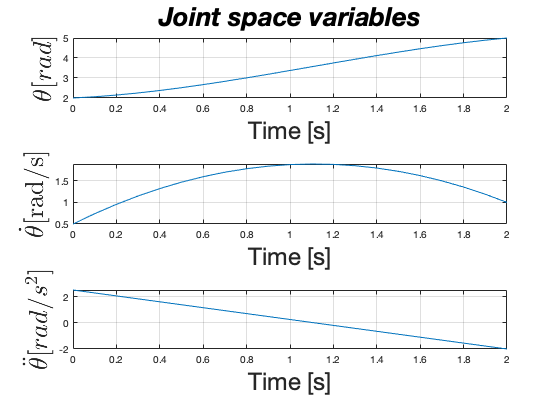

figure
subplot(3,1,1)
plot(t,q2)
title('Joint space variables','FontAngle','italic','FontSize',26);
ylabel('$\theta [rad]$','FontSize',26,'Interpreter','latex');
xlabel('Time [s]','FontSize',24);
grid on
subplot(3,1,2)
%ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
plot(t,q2_dot)
xlabel('Time [s]','FontSize',24);
ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
grid on
subplot(3,1,3)
plot(t,q2_2dot)
xlabel('Time [s]','FontSize',24);
ylabel('$\ddot \theta [rad/s^2]$','FontSize',26,'Interpreter','latex');
grid on

## Joint-space motion. Quintic interpolation

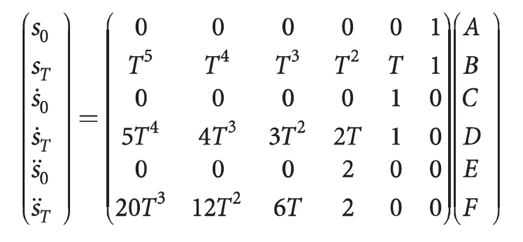

Go to help 'tpoly'

[S,SD,SDD] = tpoly(0, 1, t', 0.5, 0)

S =          0
    0.0505
    0.1033
    0.1602
    0.2218
    0.2881
    0.3586
    0.4322
    0.5075
    0.5828


SD =     0.5000
    0.5133
    0.5467
    0.5915
    0.6400
    0.6855
    0.7228
    0.7473
    0.7560
    0.7468


SDD =          0
    0.2494
    0.4050
    0.4781
    0.4800
    0.4219
    0.3150
    0.1706
    0.0000
   -0.1856


Plotting

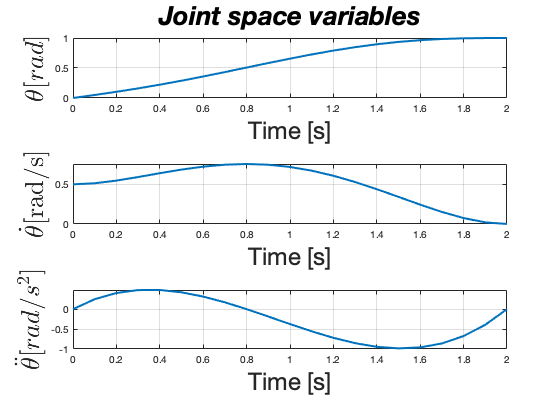

subplot(3,1,1)
plot(t,S,'linewidth',2)
title('Joint space variables','FontAngle','italic','FontSize',26);
ylabel('$\theta [rad]$','FontSize',26,'Interpreter','latex');
xlabel('Time [s]','FontSize',24);
grid on
subplot(3,1,2)
%ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
plot(t,SD,'linewidth',2)
xlabel('Time [s]','FontSize',24);
ylabel('$\dot \theta $[rad/s]','FontSize',26,'Interpreter','latex');
grid on
subplot(3,1,3)
plot(t,SDD, 'linewidth',2)
xlabel('Time [s]','FontSize',24);
ylabel('$\ddot \theta [rad/s^2]$','FontSize',26,'Interpreter','latex');
grid on

## Lineal Segment Parabolic Blend

Go to help 'lspb'

t=(0:0.01:5)

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


[S,SD,SDD] = lspb(0, 1, t')

S =          0
    0.0000
    0.0000
    0.0001
    0.0001
    0.0002
    0.0003
    0.0004
    0.0006
    0.0007


SD =          0
    0.0018
    0.0036
    0.0054
    0.0072
    0.0090
    0.0108
    0.0126
    0.0144
    0.0162


SDD =     0.1800
    0.1800
    0.1800
    0.1800
    0.1800
    0.1800
    0.1800
    0.1800
    0.1800
    0.1800


Plotting all togheter

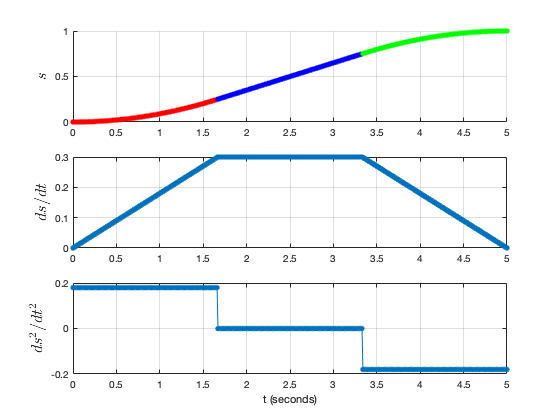

lspb(0,1, t')

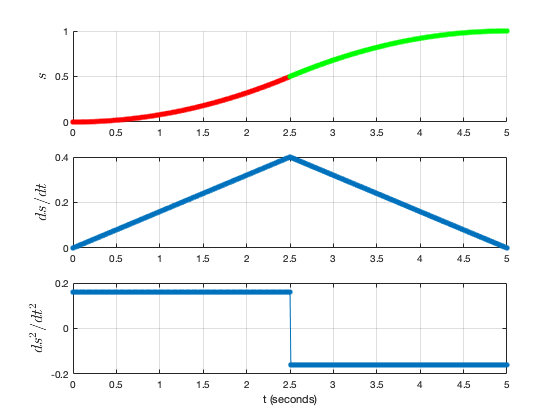

lspb(0,1, t',0.4)

## Multi-dimensional case

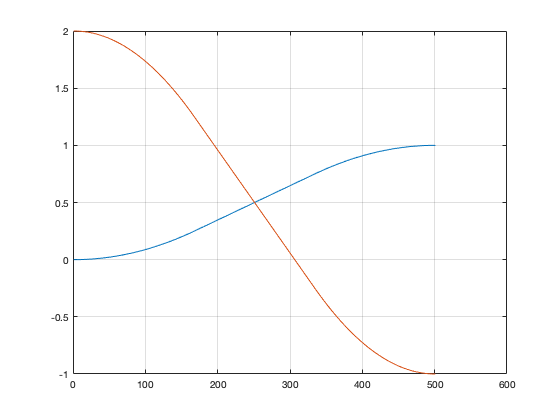

clf
q = mtraj(@lspb, [0 2], [1 -1], t');
plot(q)
grid on

## Multi-segment trajectories

Example: 2-axis motion via the corners of a rotated square can be generated ...

Try help 'mstraj'

 TRAJ = mstraj(WP, QDMAX, TSEG, Q0, DT, TACC, OPTIONS) as above but the

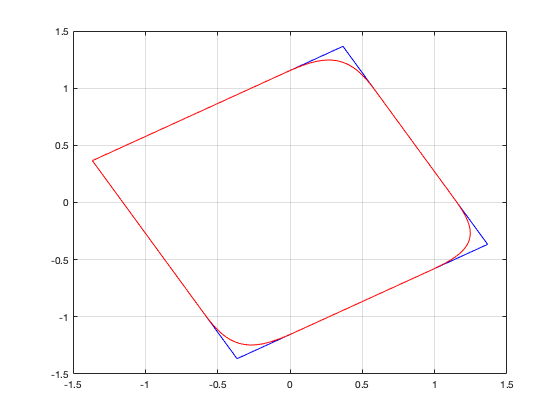

clf
via = SO2(30, 'deg') * [-1 1; 1 1; 1 -1; -1 -1]';
q0 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 0);
plot(q0(:,1), q0(:,2),'b')
hold on
q2 = mstraj(via(:,[2 3 4 1])', [2,1], [], via(:,1)', 0.2, 8);
plot(q2(:,1), q2(:,2),'r')
grid on

figure
tf=length(q2)*0.2

tf = 64

tms=(0:0.2:tf-0.2)

tms =          0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000


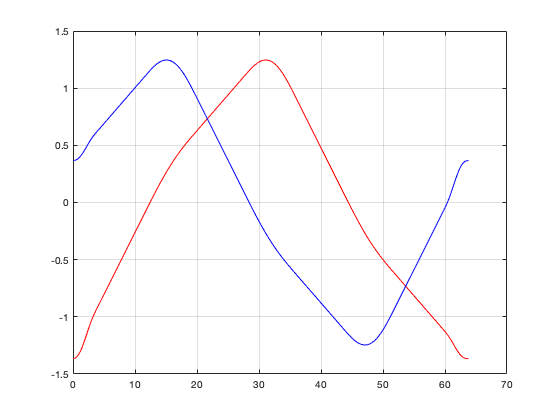

plot(tms,q2(:,1),'r')
hold on
plot(tms,q2(:,2),'b')
grid on

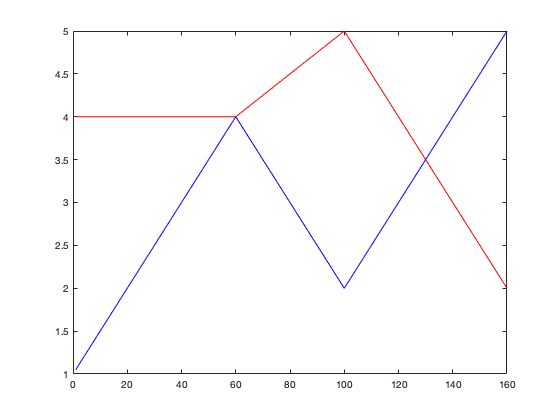

figure 
via = [ 4,1; 4,4; 5,2; 2,5 ];
q = mstraj(via, [2,1], [], [4,1], 0.05, 0);
plot(q(:,1),'r')
hold on
plot(q(:,2),'b')

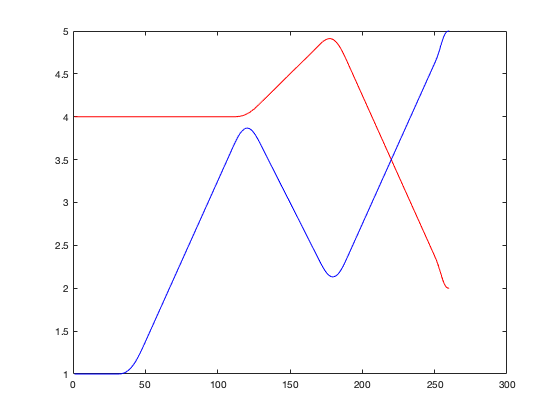

figure
via = [ 4,1; 4,4; 5,2; 2,5 ];
q = mstraj(via, [2,1], [], [4,1], 0.05, 1);
plot(q(:,1),'r')
hold on
plot(q(:,2),'b')